# **ADCIRC in MATLAB**

## Setup

See Demo1_GettingStartedWithAdcircInMatlab.mlx

## Open/plot a time-dependent time-series (station) netCDF ADCIRC file

In this part of the demo, we'll examine several time-dependent ADCIRC files, starting with the fort.63.nc file.  

urlbase='http://tds.renci.org:8080/thredds/dodsC/tc/florence/00/nc_inundation_v9.99_w_rivers/pod.penguincomputing.com/OwiHindcast/hindcast/';
ncfile='fort.72.nc';
nc72=ncgeodataset([urlbase '/' ncfile]);

% note the variables windx and windy
nc72.variables

ans = 6×1 cell array
    {'station_name'}
    {'windy'       }
    {'time'        }
    {'x'           }
    {'y'           }
    {'windx'       }

windx=nc72{'windx'};
windy=nc72{'windy'};
windx_name=windx.attribute('long_name');
windy_name=windy.attribute('long_name');
units=windx.attribute('units');

time=nc.time('time');
ntimes=size(time,1)

ntimes =         3168

time(1)

ans =    7.3731e+05

datestr(time(1))

ans = '07-Sep-2018 00:05:00'

dttime=datetime(datevec(time));
dttime(1)

ans = datetime
   07-Sep-2018 00:05:00

stations=nc72{'station_name'}

stations =   447×50 ncvariable array with properties:

       dataset: [1×1 ncgeodataset]
          name: 'station_name'
          axes: {}
    attributes: {'long_name'  'station name'}

mysta='CAPL1'

mysta = 'CAPL1'

idx=find(strcmp(cellstr(stations(:,:)),mysta))

idx =    400

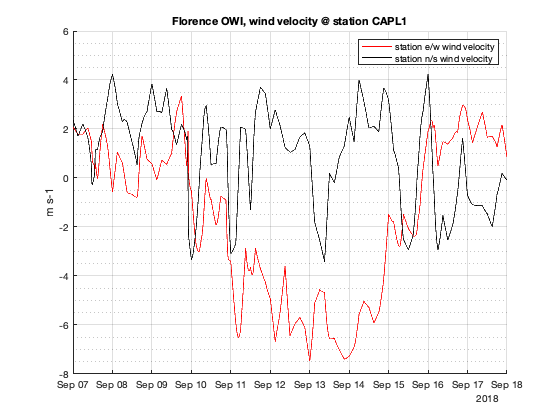

figure
line(dttime,windx(:,idx),'DisplayName',windx_name,'Color','r')
line(dttime,windy(:,idx),'DisplayName',windy_name,'Color','k')
ylabel(units)
title(['Florence OWI, wind velocity @ station ' mysta])
legend
grid on
grid minor